# Find acoustic categories using UMAP on MPS from microphone

Playing around with all experimental dates manually checked so far as data gathered from DeafBats_CatCalls1

## Project all calls from all individuals irrespective of deafening status

Select the same number of calls per individuals to obtain a fair projection of data (not biased towards a given bat)

LocalDataDir = '/Users/elie/Documents/DeafBats/Data';
BaseDataDir = '/Volumes/server_home/users/JulieE/DeafSalineGroup151/';
BaseCodeDir = '/Users/elie/Documents/CODE/GitHub/';

Loading previous data

load(fullfile(LocalDataDir, 'Data4_DeafBats_CatCalls2.mat'), 'CallType', 'BatID','MPS_mic', 'MPS_mic_wf', 'MPS_mic_wt')
load(fullfile(LocalDataDir, 'Data4_DeafBats_CatCalls.mat'),'MicAudioGood');
MicAudioGood01 = MicAudioGood;
MicAudioGood01(isnan(MicAudioGood01)) = 0;
MicAudioGood01 = logical(MicAudioGood01);

Get color vectors ready

% Get the color vector ready for call type
ColorCode = [get(groot, 'DefaultAxesColorOrder'); 0 1 1; 0.5 0.5 0.5; 1 0 0 ; 0 1 0 ; 0 0 1; 1 0 1; 0 0 0];
UCT = unique(CallType(~cellfun(@isempty, CallType)));
UCT = UCT([1:4 9 5:8 10:14])

UCT = 14×1 cell array
    {'BB' }
    {'Ba' }
    {'Bu' }
    {'Ch' }
    {'Pi' }
    {'LPi'}
    {'LT' }
    {'PB' }
    {'Pa' }
    {'Ra' }
    {'SB' }
    {'Sq' }
    {'Tr' }
    {'Un' }


UCTFull = UCT;
UCTFull{strcmp(UCT, 'Tr')} = 'Trill';
UCTFull{strcmp(UCT, 'Ba')} = 'Bark';
UCTFull{strcmp(UCT, 'Pi')} = 'Pitchy Call';
UCTFull{strcmp(UCT, 'LPi')} = 'Loud Pitchy Call';
UCTFull{strcmp(UCT, 'Bu')} = 'Low Buzz';
UCTFull{strcmp(UCT, 'Pa')} = 'Panting';
UCTFull{strcmp(UCT, 'LT')} = 'Low Tuck';
UCTFull{strcmp(UCT, 'Sq')} = 'Squeal';
UCTFull{strcmp(UCT, 'Ra')} = 'Rattle';
UCTFull{strcmp(UCT, 'Ch')} = 'Chuckles';
UCTFull{strcmp(UCT, 'BB')} = 'Bark Buzz';
UCTFull{strcmp(UCT, 'PB')} = 'Pitchy Call Buzz';
UCTFull{strcmp(UCT, 'SB')} = 'Squeal Buzz';
UCTFull{strcmp(UCT, 'Un')} = 'Unknown';
CCT = nan(length(CallType),3);
IndNoCall = cellfun(@isempty, CallType);
CallType(IndNoCall) = {'Un'};
for ct=1:length(UCT)
    CCT(contains(CallType,UCT(ct)),:) = repmat(ColorCode(ct,:),sum(contains(CallType,UCT(ct))),1);
end

% Get the color vector ready for BatName, Sex and Deafness
GGPath = dir('/Users/elie/Google Drive*');
Path2RecordingTable = fullfile(GGPath.folder, GGPath.name,'My Drive/JuvenileRecordings/DeafRecordingsNWAF155_Log.xlsx');
[~,~,RecTableData]=xlsread(Path2RecordingTable,2,'A1:k3','basic');
BatName = cell2mat(RecTableData(3,2:11));
BatSexDeaf = cell(size(BatName));
CSexDeaf =  nan(length(BatID),3);
SexDeaf =  cell(length(BatID),1);
Sex =  cell(length(BatID),1);
Deaf = cell(length(BatID),1);
CBat = nan(length(BatID),3);
UCBatName = nan(length(BatName),3);
for bat = 1:length(BatName)
    ColID = 1+ bat;
    CBat(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(bat,:),sum(contains(BatID,num2str(BatName(bat)))),1);
    UCBatName(bat,:) = ColorCode(bat,:);
    if strcmp(RecTableData(1,ColID), 'K') && strcmp(RecTableData(2,ColID), 'M')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(1,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'DM'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'M'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'D'};
        BatSexDeaf{bat} = 'Deaf Male';
    elseif strcmp(RecTableData(1,ColID), 'S') && strcmp(RecTableData(2,ColID), 'M')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(6,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'HM'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'M'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'H'};
        BatSexDeaf{bat} = 'Hearing Male';
    elseif strcmp(RecTableData(1,ColID), 'S') && strcmp(RecTableData(2,ColID), 'F')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(3,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'HF'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'F'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'H'};
        BatSexDeaf{bat} = 'Hearing Female';
    elseif strcmp(RecTableData(1,ColID), 'K') && strcmp(RecTableData(2,ColID), 'F')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(2,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'DF'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'F'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'D'};
        BatSexDeaf{bat} = 'Deaf Female';
    end
    
end
USexDeaf = {'Deaf Male' 'Hearing Male' 'Deaf Female' 'Hearing Female'};
UCSexDeaf = ColorCode([1 6 2 3], :);
BatName = BatName([1:7 10 8:9]);
BatSexDeaf = BatSexDeaf([1:7 10 8:9]);
UCBatName = UCBatName([1:7 10 8:9],:);
UCBatNameSexDeaf = ColorCode([2 2 2 3 3 3 1 1 6 6], :);

First restrict the MPS spectral frequency to 3 cycles/kHz and normalized all MPS

addpath(genpath('/Users/elie/Documents/CODE/GitHub/umapDistribution'))
IndWf = (MPS_mic_wf*1000)<=3; % Max Spectral frequency taken into account in cycles/kHz
NVoc = sum(MicAudioGood01);
MPS_mic_norm = cell(1,NVoc);
MPS_mic_focus = cell(1,NVoc);
MPS_mic_mean = reshape(mean(MPS_mic(MicAudioGood01,:), 'omitnan')',length(MPS_mic_wf), length(MPS_mic_wt));
IndMicAudioGood = find(MicAudioGood01);
for nn=1:NVoc
    vv=IndMicAudioGood(nn);
    MPS_local = reshape(MPS_mic(vv,:)',length(MPS_mic_wf), length(MPS_mic_wt));
    MPS_local = MPS_local(IndWf,:);
    MPS_mic_norm{nn} = reshape(MPS_local./MPS_mic_mean(IndWf,:), numel(MPS_local),1);
    MPS_mic_focus{nn} = reshape(MPS_local, numel(MPS_local),1);
end
MPS_mic_norm = [MPS_mic_norm{:}]';
MPS_mic_focus = [MPS_mic_focus{:}]';
CCT_mic = CCT(MicAudioGood01,:);

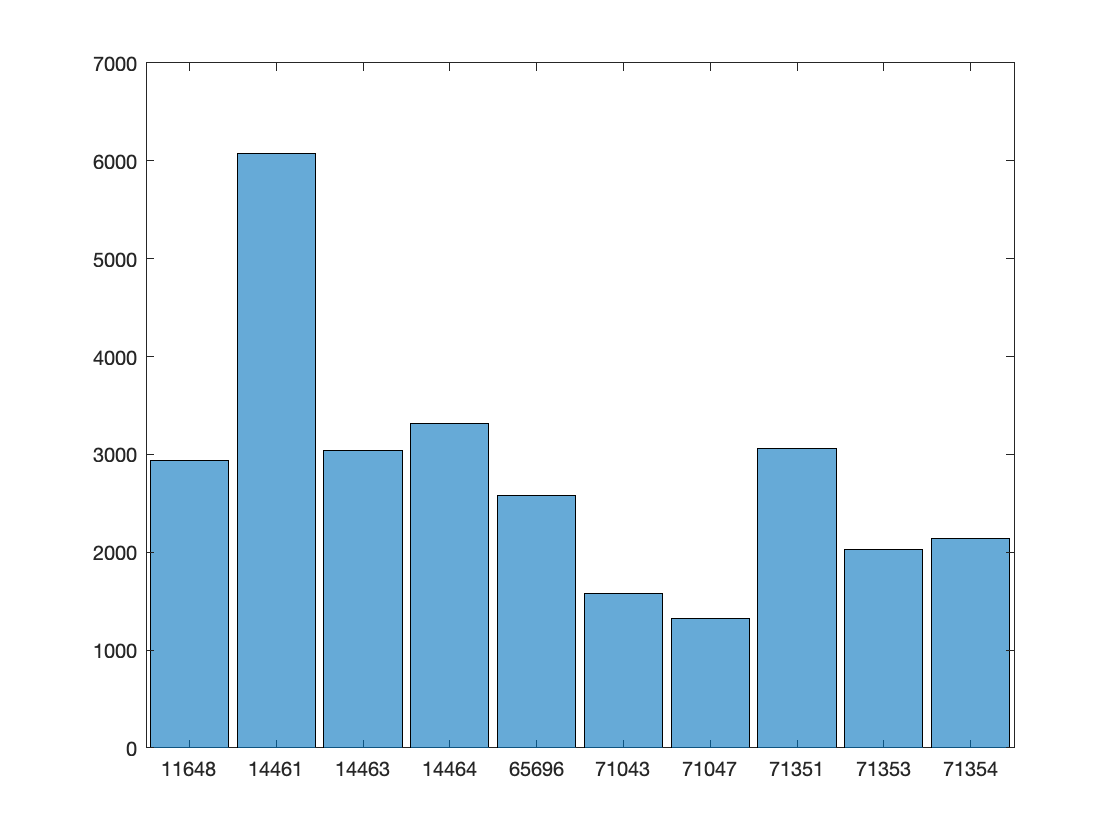

% Find the minimum number of calls per individual
figure()
H=histogram(categorical(BatID(MicAudioGood01)));

MinCall = min(H.Values)

MinCall = 1322

MPS_norm_eq = nan(MinCall*length(BatName),size(MPS_mic_norm,2));
IndMPS_norm_eq = nan(MinCall*length(BatName),1);
for bb=1:length(BatName)
    IndBat = find(strcmp(BatID(MicAudioGood01), num2str(BatName(bb))));
    if length(IndBat)>MinCall
        IndBat = IndBat(randperm(MinCall));
    end
    MPS_norm_eq((bb-1)*MinCall+1 : bb*MinCall, :) = MPS_mic_norm(IndBat,:);
    IndMPS_norm_eq((bb-1)*MinCall+1 : bb*MinCall, :) = IndBat;
end

% 
[PC,Score,~, ~, VarExpl,~] = pca(MPS_norm_eq);

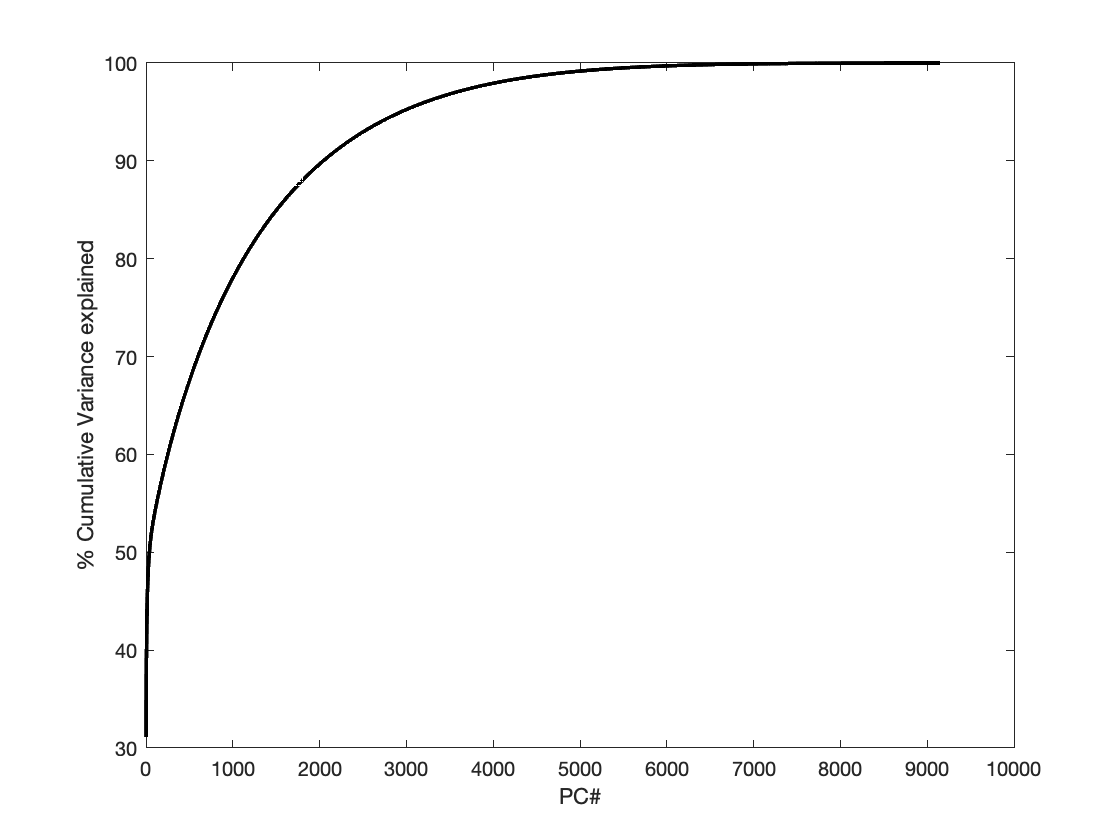

figure()
plot(cumsum(VarExpl), 'k-','LineWidth',2);
xlabel('PC#')
ylabel('% Cumulative Variance explained')

fprintf(1,'Number of PC to reach 90%% of variance = %d\n', find(cumsum(VarExpl)>90,1))

Number of PC to reach 90% of variance = 2044


fprintf(1,'Number of PC to reach 80%% of variance = %d\n', find(cumsum(VarExpl)>80,1))

Number of PC to reach 80% of variance = 1124


% !!!! Run these lines in command window to avoid Java error
[MPSmicReduction4ClusteringEq,umap]= run_umap(MPS_norm_eq, 'metric','euclidean','n_component',50,'target_weight',0.55, 'n_neighbors',10, 'min_dist',0.051);
save(fullfile(LocalDataDir, 'UMAPmic4ClusteringEq.mat'),'umap') % save to be able to then project all bats vocalizations in the same space 

Using MPS of all bats calculate an agglomerative hierarchical cluster tree Z

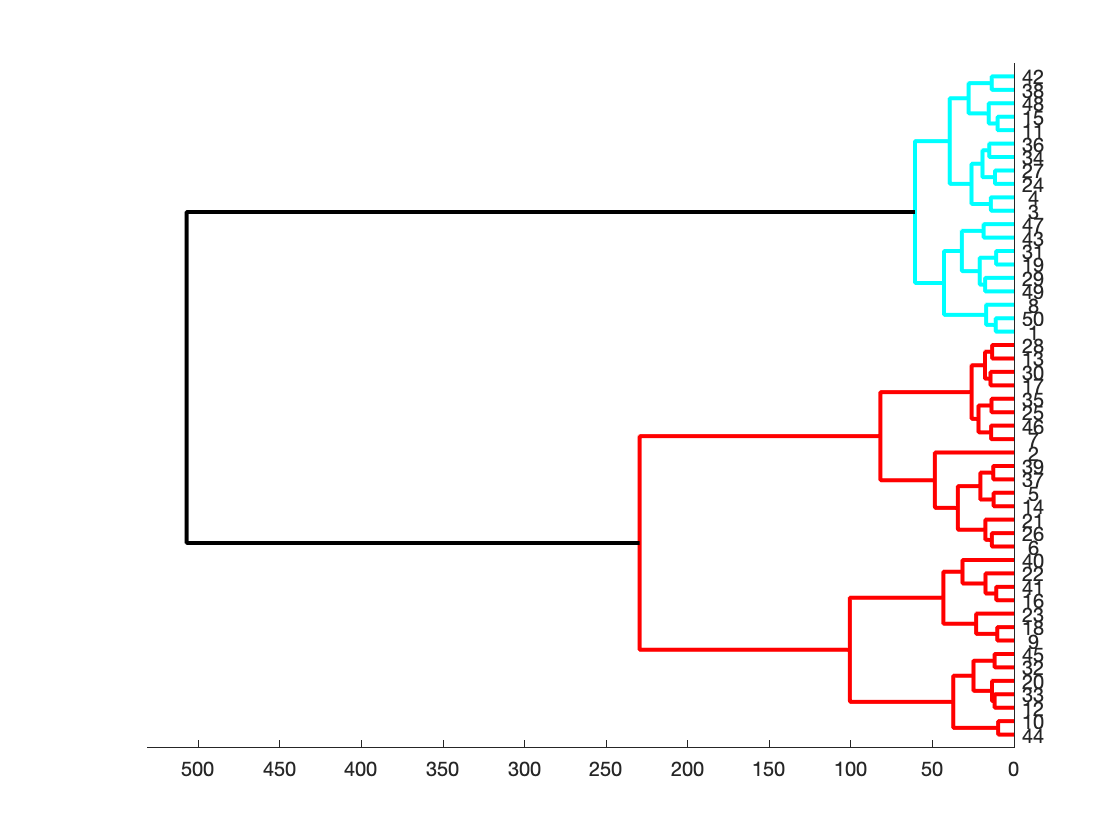

Z = linkage( MPSmicReduction4ClusteringEq,'ward','euclidean');
% Cut the tree at first level and plot dendogram
[D1, T1, ~] = dendrogram(Z,50, 'ColorThreshold','Default','Orientation','left');
set(D1,'LineWidth',2)

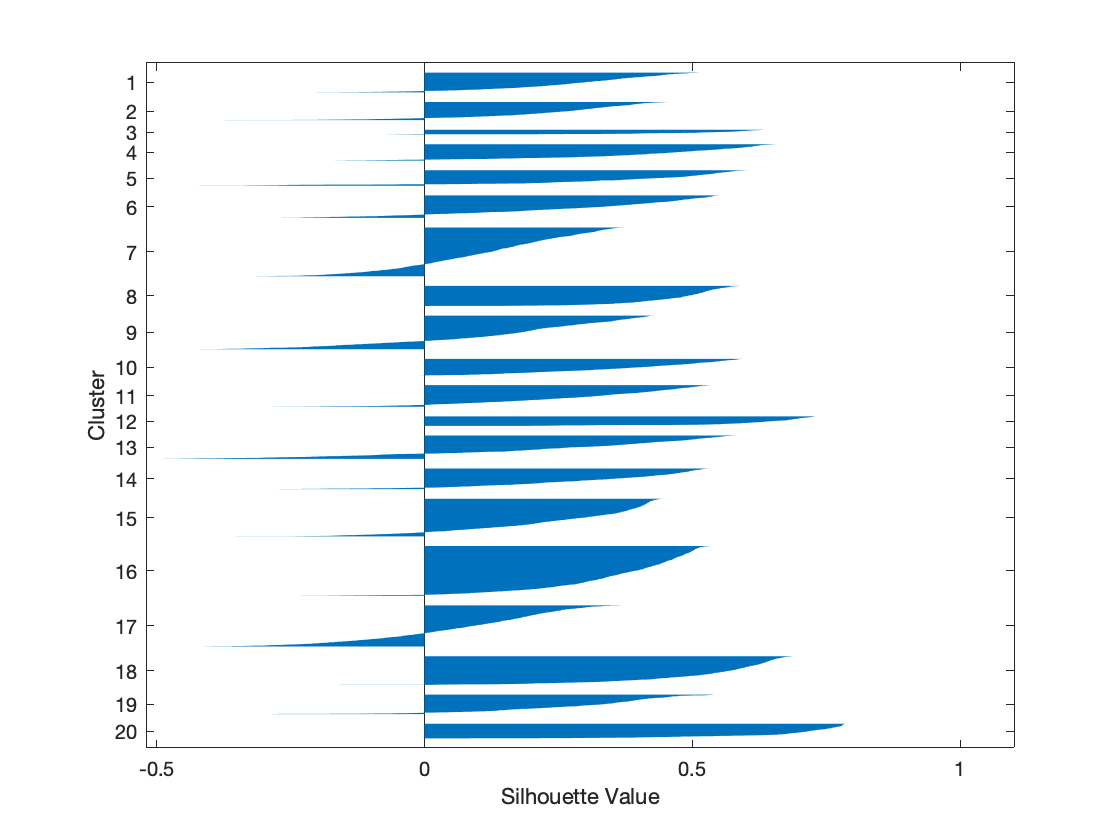

% Evaluate cluster quality accross various tree cut levels
ClustSize = 2:20;
MeanSilhouette = nan(size(ClustSize));
MedianSilhouette = nan(size(ClustSize));
PercLowSilhouette = nan(size(ClustSize));
LowSi = 0.3;
for cc=1:length(ClustSize)
    T = cluster(Z,'maxclust',ClustSize(cc));
    [Si,h] = silhouette(MPSmicReduction4ClusteringEq,T, 'Euclidean');
    MeanSilhouette(cc) = mean(Si);
    MedianSilhouette(cc) = median(Si);
    PercLowSilhouette(cc) = sum(Si<LowSi)/length(Si);
end

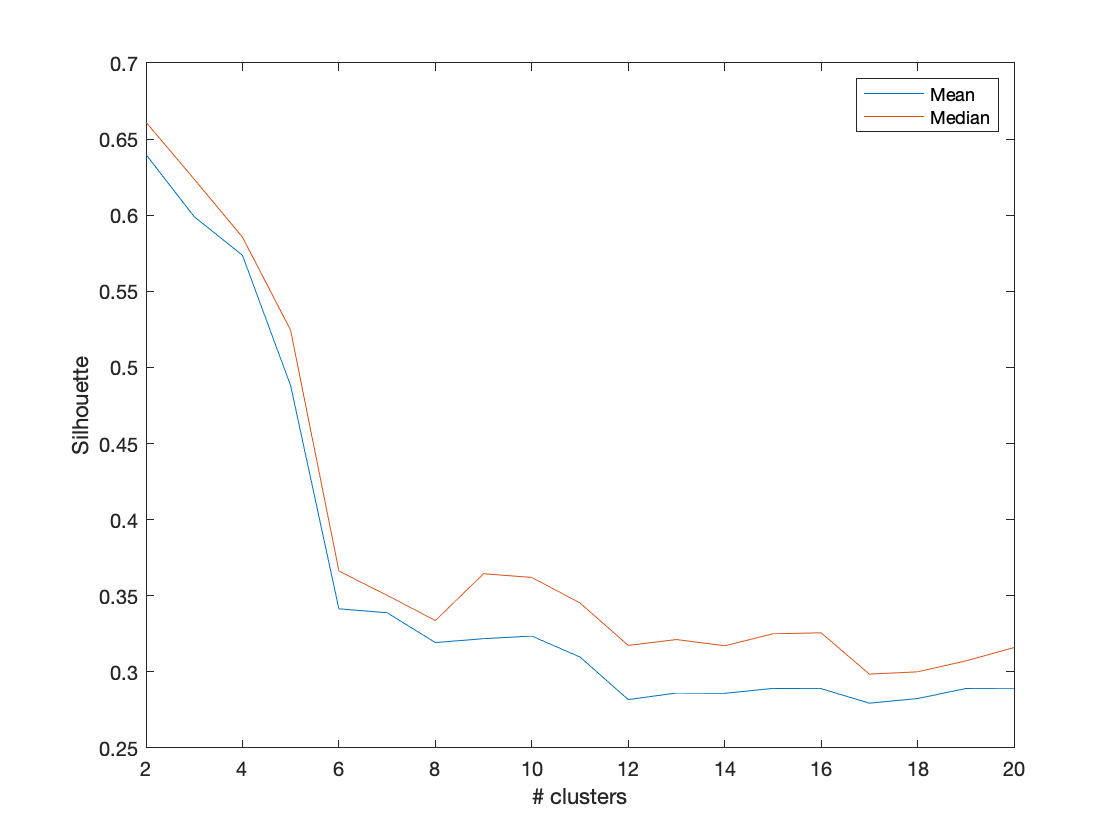

figure()
plot(2:20,MeanSilhouette)
hold on
plot(2:20,MedianSilhouette)
ylabel('Silhouette')
xlabel('# clusters')
legend('Mean', 'Median')
hold off

eva = evalclusters(MPSmicReduction4ClusteringEq, 'linkage','CalinskiHarabasz','KList',1:20) %3 clusters

eva =   CalinskiHarabaszEvaluation with properties:

    NumObservations: 13220
         InspectedK: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20]
    CriterionValues: [NaN 3.3569e+04 4.2107e+04 3.6601e+04 3.3930e+04 3.1041e+04 2.8422e+04 2.6421e+04 2.5185e+04 2.4187e+04 2.3439e+04 2.2794e+04 2.2218e+04 2.1855e+04 2.1375e+04 2.0924e+04 2.0616e+04 2.0345e+04 2.0063e+04 1.9770e+04]
           OptimalK: 3


eva = evalclusters(MPSmicReduction4ClusteringEq, 'linkage','DaviesBouldin','KList',1:20) % 2 clusters

eva =   DaviesBouldinEvaluation with properties:

    NumObservations: 13220
         InspectedK: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20]
    CriterionValues: [NaN 0.5078 0.6437 0.6741 0.8444 1.1964 1.1193 1.1465 1.0884 1.1350 1.1316 1.2093 1.2002 1.1743 1.1201 1.1276 1.1996 1.1817 1.1315 1.1067]
           OptimalK: 2


eva = evalclusters(MPSmicReduction4ClusteringEq, 'linkage','silhouette','KList',1:20) %2 clusters

eva =   SilhouetteEvaluation with properties:

    NumObservations: 13220
         InspectedK: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20]
    CriterionValues: [NaN 0.8267 0.7978 0.7731 0.6732 0.4995 0.4929 0.4673 0.4692 0.4691 0.4484 0.4072 0.4111 0.4119 0.4155 0.4136 0.3978 0.4011 0.4116 0.4117]
           OptimalK: 2


Cut the Tree at 8 (NGroups) clusters and get the leaves labels (T)

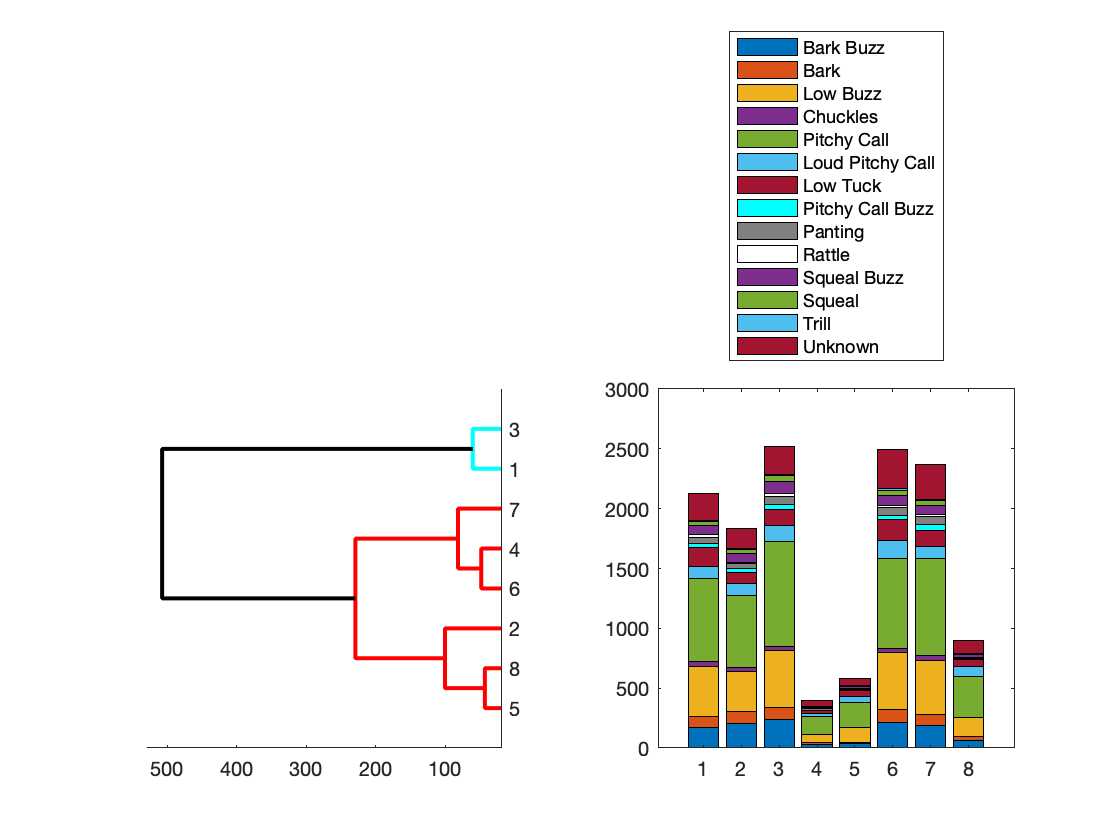

NGroups = 8;
figure()
t=tiledlayout(1,2);
CTinCluster = nan(NGroups,length(UCT));
nexttile
[D, TEq, ~] = dendrogram(Z,NGroups, 'ColorThreshold','Default','Orientation','left');
set(D,'LineWidth',2)
for cc=1:NGroups
    for ct=1:length(UCT)
        CTinCluster(cc,ct) = sum(strcmp(CallType(TEq==cc), UCT{ct}));
    end
end
nexttile
B = bar(CTinCluster, 'stacked');
B(8).FaceColor = ColorCode(8,:);
B(9).FaceColor = ColorCode(9,:);
B(10).FaceColor = [1 1 1];
legend(UCTFull, 'Location', 'northoutside')

figure()
t=tiledlayout(1,2);
CTin15Cluster = nan(15,10);
nexttile
[D15, T15, ~] = dendrogram(Z,15, 'ColorThreshold','Default','Orientation','left');
set(D15,'LineWidth',2)
for cc=1:15
    for ct=1:length(UCT)
        CTin15Cluster(cc,ct) = sum(strcmp(CallType(T15==cc), UCT{ct}));
    end
end
nexttile
B= bar(CTin15Cluster, 'stacked');
B(8).FaceColor = ColorCode(8,:);
B(9).FaceColor = ColorCode(9,:);
B(10).FaceColor = [1 1 1];
legend(UCTFull, 'Location', 'northoutside')

Project the vocalizations in 3D UMAP space and colorcode according to acoustic hierarchical agglomerative clusters.

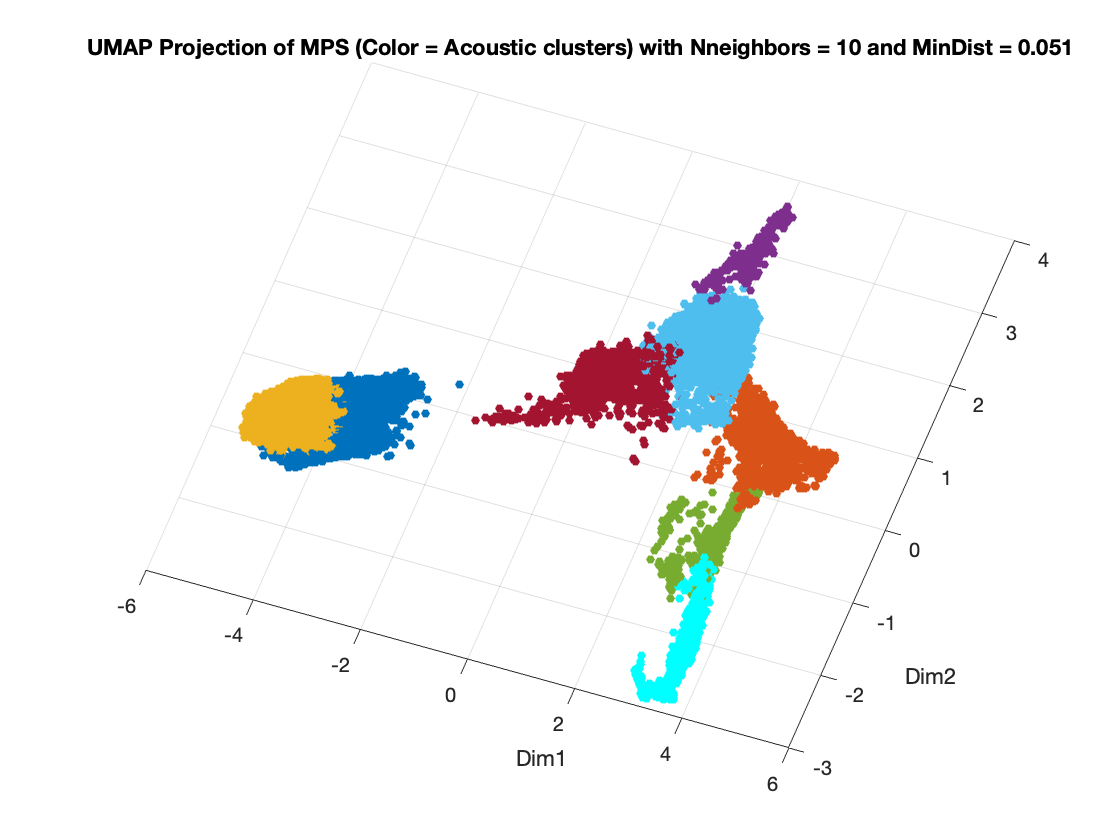

%%
figure()
scatter3(MPSmicReduction4ClusteringEq(:,1), MPSmicReduction4ClusteringEq(:,2),MPSmicReduction4ClusteringEq(:,3),20,ColorCode(TEq,:,:),'filled')
xlabel('Dim1')
ylabel('Dim2')
zlabel('Dim3')
title('UMAP Projection of MPS (Color = Acoustic clusters) with Nneighbors = 10 and MinDist = 0.051')

view([19.30 90.00])

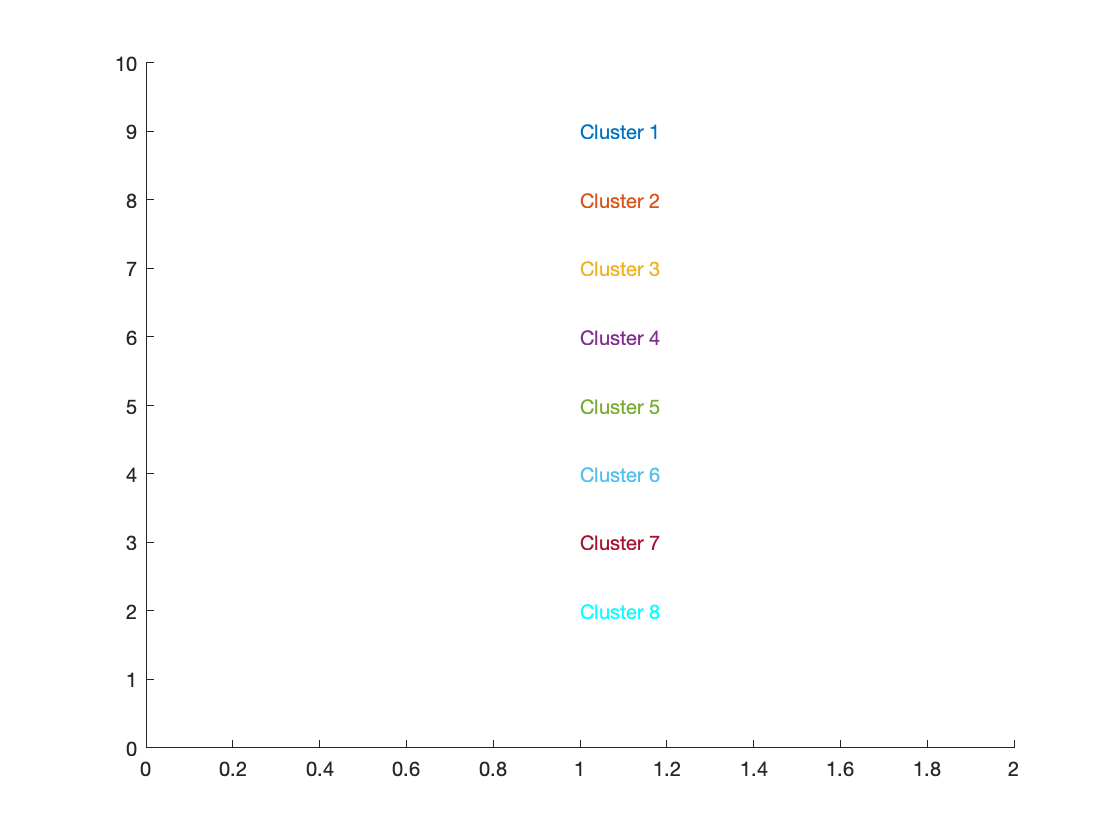

figure(); xlim([0 2]); ylim([0 10]);for gg=1:8; text(1,10-gg, sprintf('Cluster %d',gg), 'Color', ColorCode(gg,:)); end

Project all the dta to see what clustering we would obtain

You want to run these lines in the command window as the code open multiple figures and that messes up with the livescripts

[MPSmicReduction4Clustering,UMAP]= run_umap(MPS_mic_norm, 'metric','euclidean','n_component',3,'target_weight',0.55,'n_neighbors',10, 'min_dist',0.051);

Using MPS of all bats calculate an agglomerative hierarchical cluster tree Z

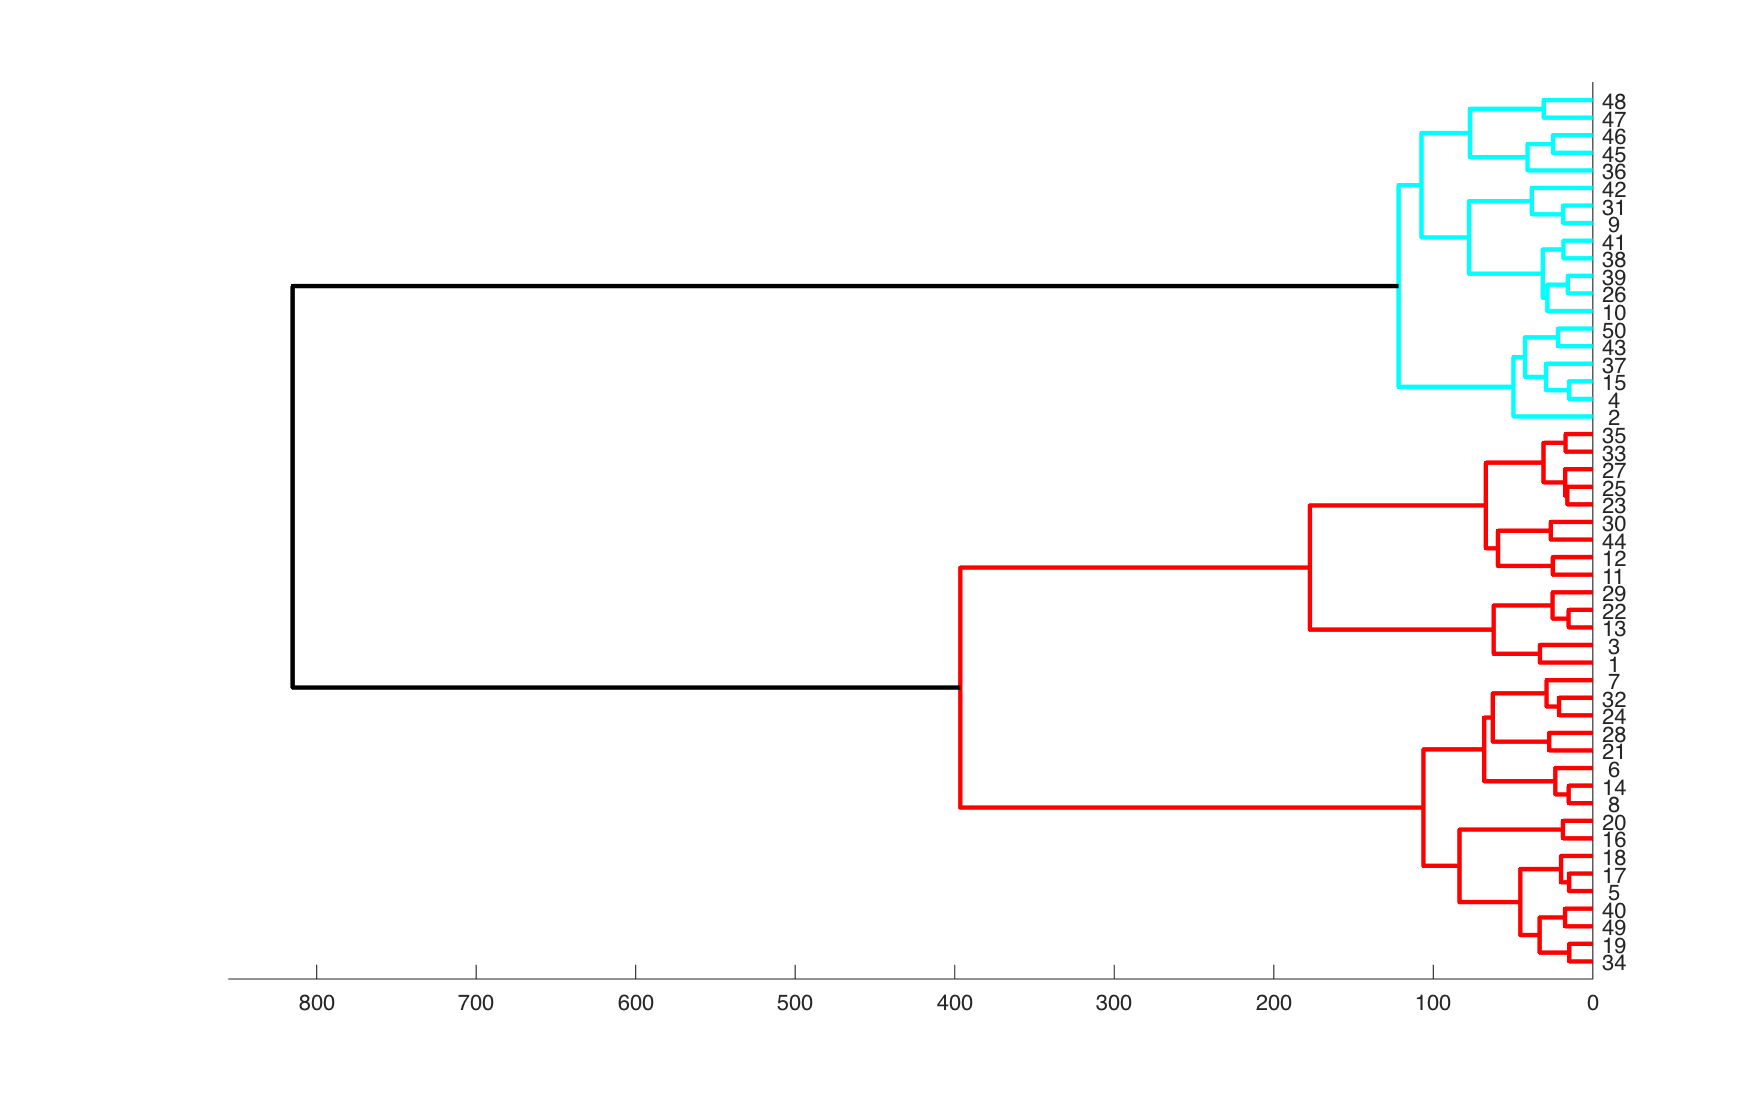

Z = linkage( MPSmicReduction4Clustering,'ward','euclidean');
% Cut the tree at first level and plot dendogram
[D1, T1, ~] = dendrogram(Z,50, 'ColorThreshold','Default','Orientation','left');
set(D1,'LineWidth',2)

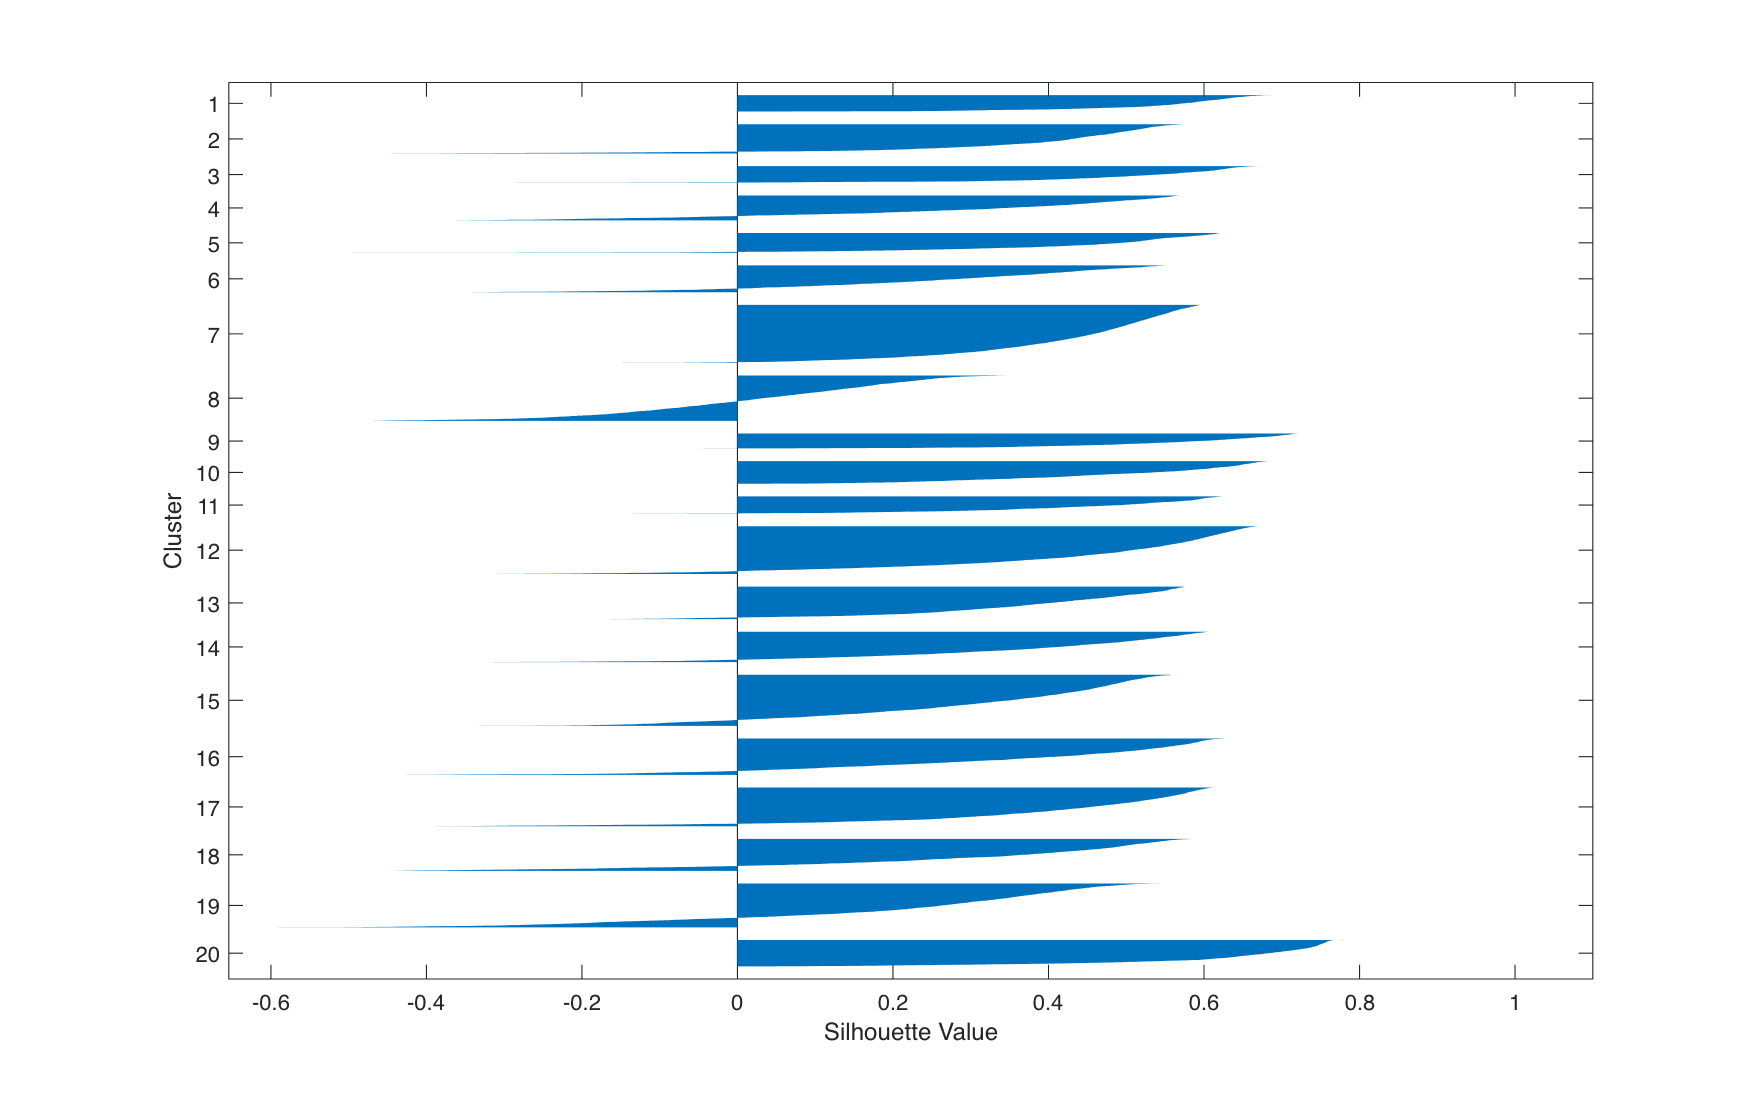

% Evaluate cluster quality accross various tree cut levels
ClustSize = 2:20;
MeanSilhouette = nan(size(ClustSize));
MedianSilhouette = nan(size(ClustSize));
PercLowSilhouette = nan(size(ClustSize));
LowSi = 0.3;
for cc=1:length(ClustSize)
    T = cluster(Z,'maxclust',ClustSize(cc));
    [Si,h] = silhouette(MPSmicReduction4Clustering,T, 'Euclidean');
    MeanSilhouette(cc) = mean(Si);
    MedianSilhouette(cc) = median(Si);
    PercLowSilhouette(cc) = sum(Si<LowSi)/length(Si);
end

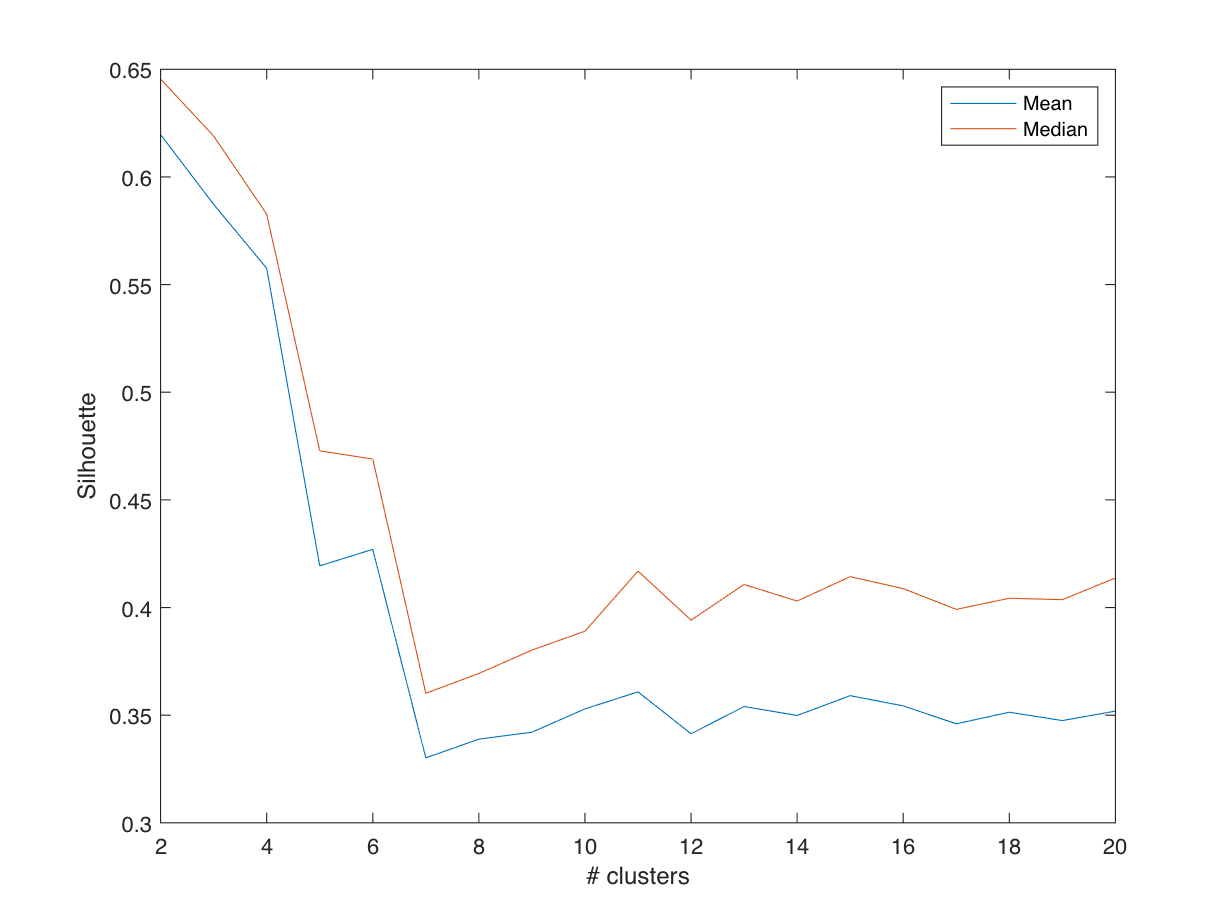

figure()
plot(2:20,MeanSilhouette)
hold on
plot(2:20,MedianSilhouette)
ylabel('Silhouette')
xlabel('# clusters')
legend('Mean', 'Median')
hold off

eva = evalclusters(MPSmicReduction4Clustering, 'linkage','CalinskiHarabasz','KList',1:15) %3 clusters

eva =   CalinskiHarabaszEvaluation with properties:

    NumObservations: 28091
         InspectedK: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15]
    CriterionValues: [NaN 6.1295e+04 7.8370e+04 6.8983e+04 6.0359e+04 5.5238e+04 5.3345e+04 5.0603e+04 4.8686e+04 4.7918e+04 4.7023e+04 4.6811e+04 4.6756e+04 4.7292e+04 4.8095e+04]
           OptimalK: 3


eva = evalclusters(MPSmicReduction4Clustering, 'linkage','DaviesBouldin','KList',1:15) % 2 clusters

eva =   DaviesBouldinEvaluation with properties:

    NumObservations: 28091
         InspectedK: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15]
    CriterionValues: [NaN 0.5591 0.6327 0.6494 0.9633 1.0088 1.1964 1.0956 1.0107 0.9674 0.9387 0.9936 0.9411 0.9546 0.8937]
           OptimalK: 2


eva = evalclusters(MPSmicReduction4Clustering, 'linkage','silhouette','KList',1:15) % 2 clusters

eva =   SilhouetteEvaluation with properties:

    NumObservations: 28091
         InspectedK: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15]
    CriterionValues: [NaN 0.8102 0.7851 0.7628 0.5940 0.6048 0.4709 0.4766 0.4768 0.4930 0.5016 0.4723 0.4938 0.4910 0.5052]
           OptimalK: 2


Cut the Tree at 4 (NGroups) clusters and get the leaves labels (T)

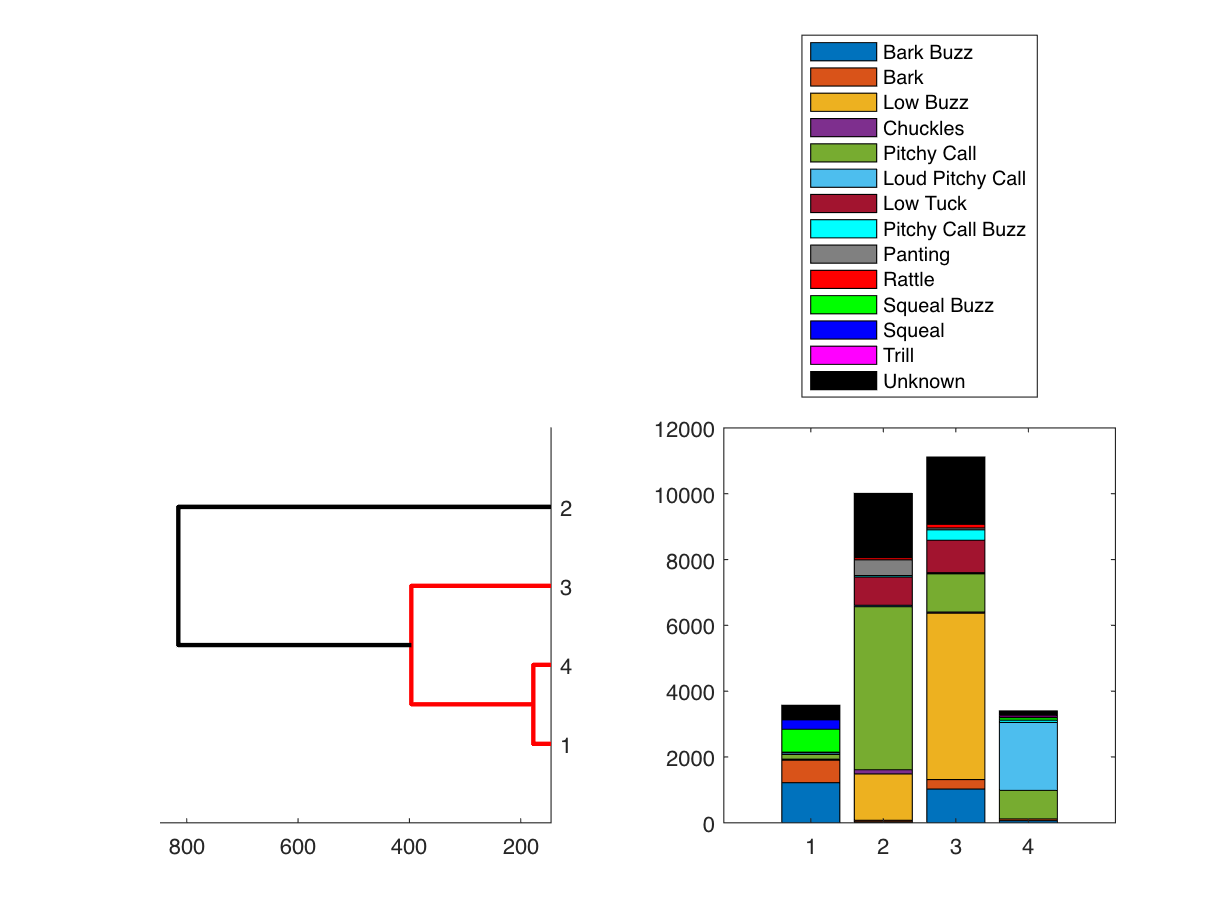

NGroups = 4;
figure()
t=tiledlayout(1,2);
CTinCluster = nan(NGroups,length(UCT));
nexttile
[D, TmicAll, ~] = dendrogram(Z,NGroups, 'ColorThreshold','Default','Orientation','left');
set(D,'LineWidth',2)
CallTypeMicAudioGood = CallType(MicAudioGood01);
for cc=1:NGroups
    for ct=1:length(UCT)
        CTinCluster(cc,ct) = sum(strcmp(CallTypeMicAudioGood(TmicAll==cc), UCT{ct}));
    end
end
nexttile
B = bar(CTinCluster, 'stacked');
B(8).FaceColor = ColorCode(8,:);
B(9).FaceColor = ColorCode(9,:);
B(10).FaceColor = ColorCode(10,:);
B(11).FaceColor = ColorCode(11,:);
B(12).FaceColor = ColorCode(12,:);
B(13).FaceColor = ColorCode(13,:);
B(14).FaceColor = ColorCode(14,:);
legend(UCTFull, 'Location', 'northoutside')

Project the vocalizations in 3D UMAP space and colorcode according to acoustic hierarchical agglomerative clusters.

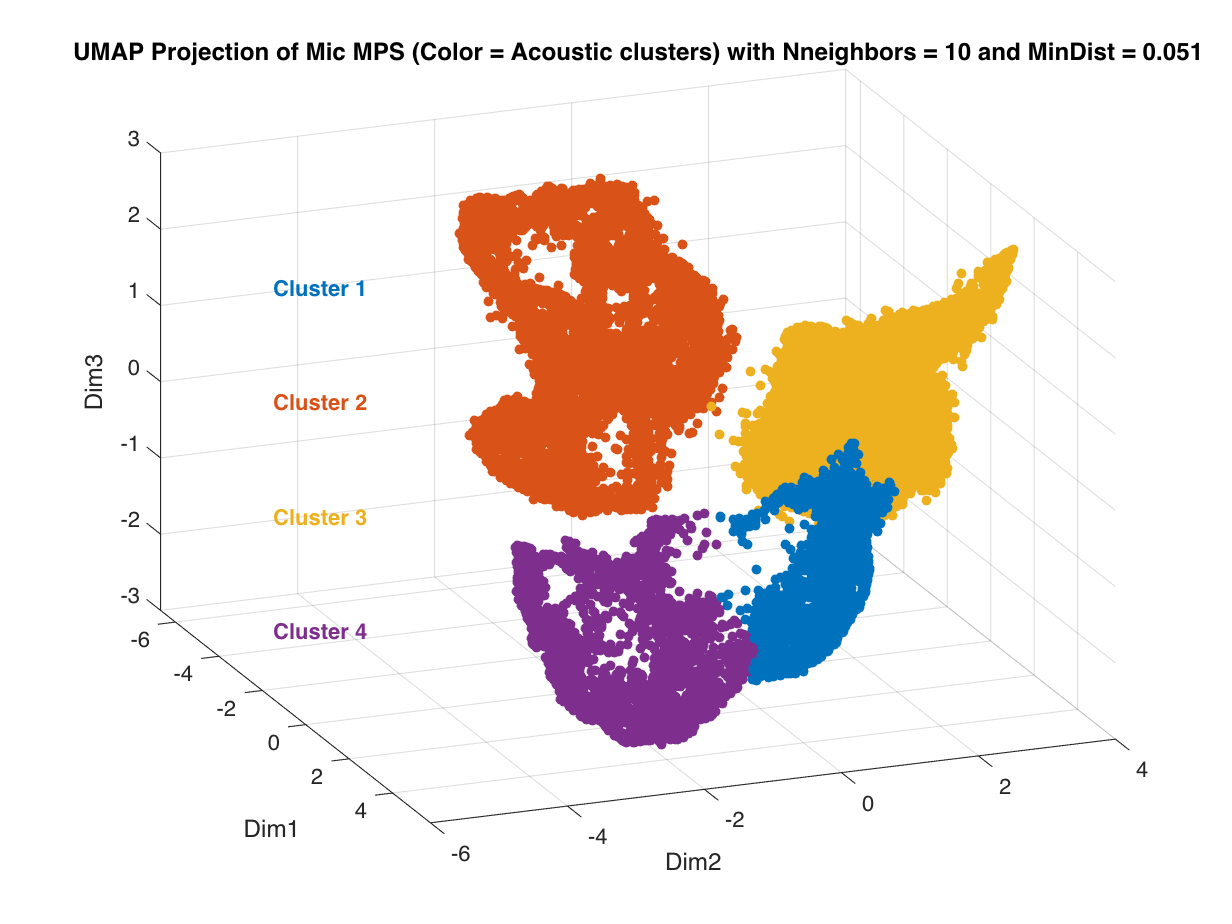

%%
figure()
scatter3(MPSmicReduction4Clustering(:,1), MPSmicReduction4Clustering(:,2),MPSmicReduction4Clustering(:,3),20,ColorCode(TmicAll,:,:),'filled')
xlabel('Dim1')
ylabel('Dim2')
zlabel('Dim3')
ZLim = get(gca, 'ZLim');
title('UMAP Projection of Mic MPS (Color = Acoustic clusters) with Nneighbors = 10 and MinDist = 0.051')
for gg=1:NGroups
    text(-5,-4.9, ZLim(2)-diff(ZLim)*gg/NGroups, sprintf('Cluster %d',gg), 'Color',ColorCode(gg,:), 'FontWeight','bold' )
end
view([68.50 26.52])

Cut the Tree at 7 (NGroups) clusters and get the leaves labels (TmicAll7)

Silhouette calculations show that 7 is the value for which we have minimum meana nd median Silhouette and almost max Perc of Low silhouette (6 cluster would be max for that respect)

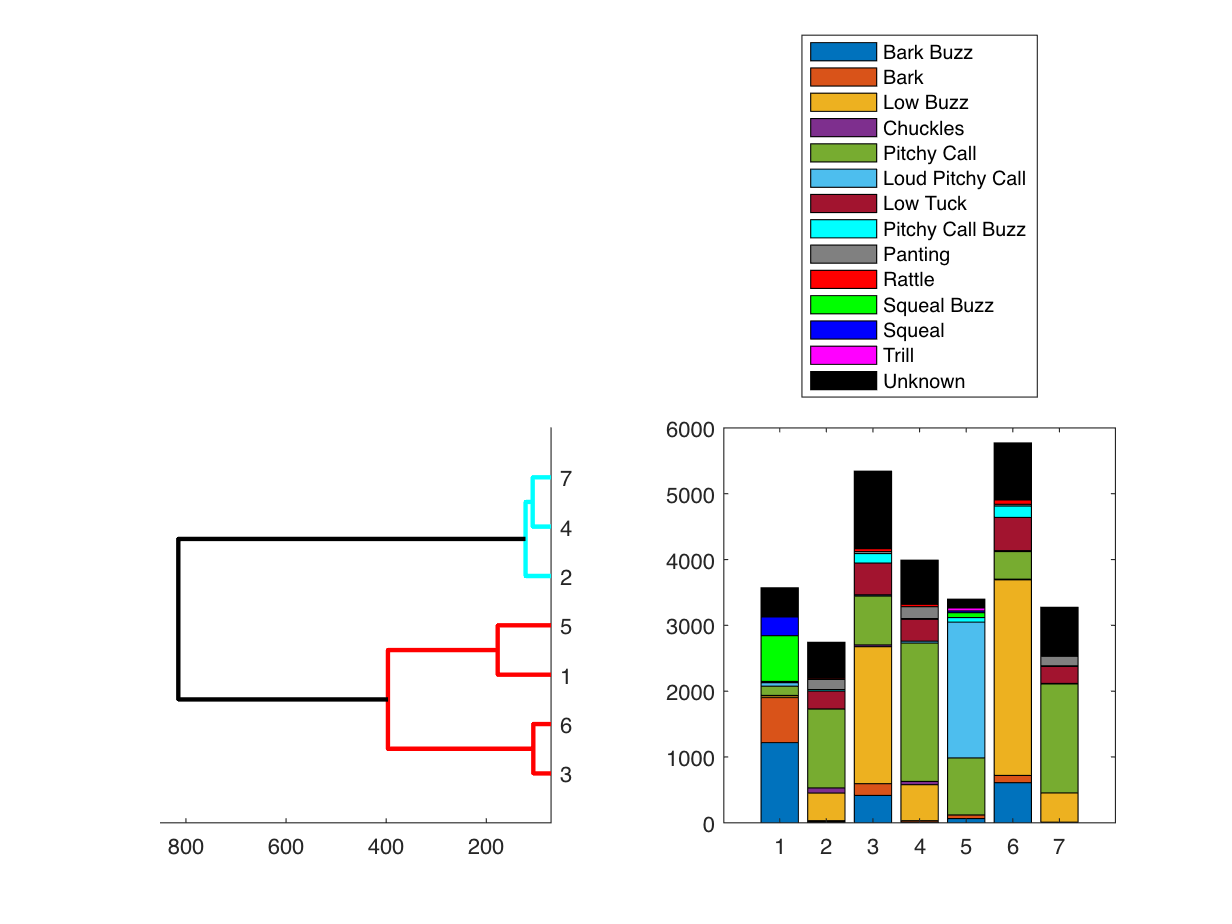

NGroups = 7;
figure()
t=tiledlayout(1,2);
CTinCluster7 = nan(NGroups,length(UCT));
nexttile
[D, TmicAll7, ~] = dendrogram(Z,NGroups, 'ColorThreshold','Default','Orientation','left');
set(D,'LineWidth',2)
CallTypeMicAudioGood = CallType(MicAudioGood01);
for cc=1:NGroups
    for ct=1:length(UCT)
        CTinCluster7(cc,ct) = sum(strcmp(CallTypeMicAudioGood(TmicAll7==cc), UCT{ct}));
    end
end
nexttile
B = bar(CTinCluster7, 'stacked');
B(8).FaceColor = ColorCode(8,:);
B(9).FaceColor = ColorCode(9,:);
B(10).FaceColor = ColorCode(10,:);
B(11).FaceColor = ColorCode(11,:);
B(12).FaceColor = ColorCode(12,:);
B(13).FaceColor = ColorCode(13,:);
B(14).FaceColor = ColorCode(14,:);
legend(UCTFull, 'Location', 'northoutside')


Project the vocalizations in 3D UMAP space and colorcode according to acoustic hierarchical agglomerative clusters.

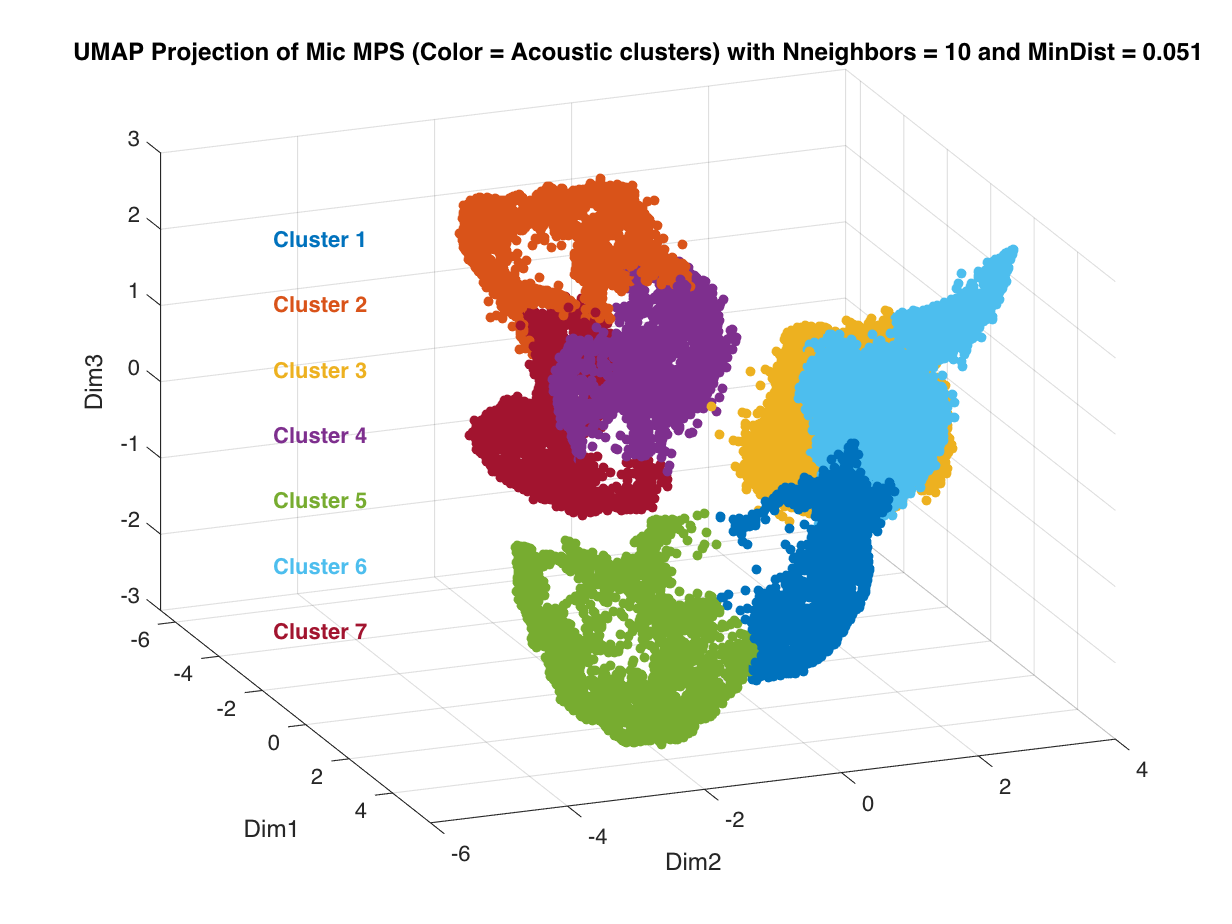

%%
figure()
scatter3(MPSmicReduction4Clustering(:,1), MPSmicReduction4Clustering(:,2),MPSmicReduction4Clustering(:,3),20,ColorCode(TmicAll7,:,:),'filled')
xlabel('Dim1')
ylabel('Dim2')
zlabel('Dim3')
ZLim = get(gca, 'ZLim');
title('UMAP Projection of Mic MPS (Color = Acoustic clusters) with Nneighbors = 10 and MinDist = 0.051')
for gg=1:NGroups
    text(-5,-4.9, ZLim(2)-diff(ZLim)*gg/NGroups, sprintf('Cluster %d',gg), 'Color',ColorCode(gg,:), 'FontWeight','bold' )
end
view([68.50 26.52])

Project the vocalizations in 3D UMAP space and colorcode according to Manual classification into call type

%%
figure()
scatter3(MPSmicReduction4Clustering(:,1), MPSmicReduction4Clustering(:,2),MPSmicReduction4Clustering(:,3),20,CCT_mic,'filled')
xlabel('Dim1')
ylabel('Dim2')
zlabel('Dim3')
title('UMAP Projection of MPS (Color = Manual CT) with Nneighbors = 10 and MinDist = 0.051')
for ct=1:length(UCTFull)
    text(-5,-4.9, ZLim(2)-diff(ZLim)*ct/15, UCTFull(ct), 'Color',ColorCode(ct,:), 'FontWeight','bold' )
end
view([75.35 34.65])
IndCall = logical((~strcmp(CallType(IndMicAudioGood), 'Un')).*(~strcmp(CallType(IndMicAudioGood), 'BB')).*(~strcmp(CallType(IndMicAudioGood), 'PB')).*(~strcmp(CallType(IndMicAudioGood), 'SB')));

scatter3(MPSmicReduction4Clustering(IndCall,1), MPSmicReduction4Clustering(IndCall,2),MPSmicReduction4Clustering(IndCall,3),20,CCT_mic(IndCall,:,:),'filled')
xlabel('Dim1')
ylabel('Dim2')
zlabel('Dim3')
YLim = get(gca, 'ylim');
ZLim = get(gca, 'zlim');
XLim = get(gca, 'xlim');
CT_used = [2 3 4 5 6 7 9 10 12 13];
UCTFull_used=UCTFull(CT_used);
ColorCode_used = ColorCode(CT_used,:);
for ct=1:length(CT_used)
    text(-5,-4.9, ZLim(2)-diff(ZLim)*ct/10, UCTFull_used(ct), 'Color',ColorCode_used(ct,:), 'FontWeight','bold' )
end
view([75.35 34.65])

figure();
scatter3(MPSmicReduction4Clustering(strcmp(Deaf(IndMicAudioGood),'H'),1), MPSmicReduction4Clustering(strcmp(Deaf(IndMicAudioGood),'H'),2),MPSmicReduction4Clustering(strcmp(Deaf(IndMicAudioGood),'H'),3),20,'k','filled')
hold on
scatter3(MPSmicReduction4Clustering(strcmp(Deaf(IndMicAudioGood),'D'),1), MPSmicReduction4Clustering(strcmp(Deaf(IndMicAudioGood),'D'),2),MPSmicReduction4Clustering(strcmp(Deaf(IndMicAudioGood),'D'),3),20,'r','filled')
xlabel('Dim1')
ylabel('Dim2')
zlabel('Dim3')
hold off
title('UMAP Projection of D (red) and H (black) mic MPS with Nneighbors = 10 and MinDist = 0.051')
view([75.35 34.65])


figure()
scatter3(MPSmicReduction4Clustering(:,1), MPSmicReduction4Clustering(:,2),MPSmicReduction4Clustering(:,3),20,CBat(IndMicAudioGood,:),'filled')
xlabel('Dim1')
ylabel('Dim2')
zlabel('Dim3')
title(sprintf('UMAP Mic Projection of Normalized MPS (Color = BatID) with Nneighbors = %d and MinDist = %.2f', NNeigh, MinDist))
XLim = get(gca, 'XLim');
YLim = get(gca, 'YLim');
ZLim = get(gca, 'ZLim');
for ct=1:10
    text(XLim(2),diff(YLim)+YLim(1),ZLim(2)-diff(YLim)*(2+ct)/30, num2str(BatName(ct)), 'Color',UCBatName(ct,:), 'FontWeight','bold' )
end
view([75.35 34.65])

figure()

scatter3(MPSmicReduction4Clustering(:,1), MPSmicReduction4Clustering(:,2),MPSmicReduction4Clustering(:,3),20,CSexDeaf(IndMicAudioGood,:),'filled')
xlabel('Dim1')
ylabel('Dim2')
zlabel('Dim3')
title(sprintf('UMAP Mic Projection of Normalized MPS (Color = SexExp) with Nneighbors = %d and MinDist = %.2f', NNeigh, MinDist))
XLim = get(gca, 'XLim');
YLim = get(gca, 'YLim');
ZLim = get(gca, 'ZLim');
for ct=1:10
    text(XLim(2),diff(YLim)+YLim(1),ZLim(2)-diff(YLim)*(2+ct)/30, num2str(BatName(ct)), 'Color',UCBatNameSexDeaf(ct,:), 'FontWeight','bold' )
end
view([75.35 34.65])

figure()

CSexDeaf_mic = CSexDeaf(IndMicAudioGood,:);
IndCall = contains(SexDeaf(IndMicAudioGood), 'F');
scatter3(MPSmicReduction4Clustering(IndCall,1), MPSmicReduction4Clustering(IndCall,2),MPSmicReduction4Clustering(IndCall,3),20,CSexDeaf_mic(IndCall,:),'filled')
xlabel('Dim1')
ylabel('Dim2')
zlabel('Dim3')
title(sprintf('UMAP Mic Projection of Normalized MPS (Color = SexExp) with Nneighbors = %d and MinDist = %.2f', NNeigh, MinDist))
XLim = get(gca, 'XLim');
YLim = get(gca, 'YLim');
ZLim = get(gca, 'ZLim');
for ct=1:6
    text(XLim(2),diff(YLim)+YLim(1),ZLim(2)-diff(YLim)*(2+ct)/30, num2str(BatName(ct)), 'Color',UCBatNameSexDeaf(ct,:), 'FontWeight','bold' )
end
view([75.35 34.65])

figure()

IndCall = contains(SexDeaf(IndMicAudioGood), 'M');
scatter3(MPSmicReduction4Clustering(IndCall,1), MPSmicReduction4Clustering(IndCall,2),MPSmicReduction4Clustering(IndCall,3),20,CSexDeaf_mic(IndCall,:),'filled')
xlabel('Dim1')
ylabel('Dim2')
zlabel('Dim3')
title(sprintf('UMAP Mic Projection of Normalized MPS (Color = SexExp) with Nneighbors = %d and MinDist = %.2f', NNeigh, MinDist))
XLim = get(gca, 'XLim');
YLim = get(gca, 'YLim');
ZLim = get(gca, 'ZLim');
for ct=7:10
    text(XLim(2),diff(YLim)+YLim(1),ZLim(2)-diff(YLim)*(2+ct)/30, num2str(BatName(ct)), 'Color',UCBatNameSexDeaf(ct,:), 'FontWeight','bold' )
end
view([75.35 34.65])

figure(22)

clf
set(gcf,'Visible','on')
tiledlayout(1,2)
nexttile
IndCall = contains(SexDeaf(IndMicAudioGood), 'HM');
scatter3(MPSmicReduction4Clustering(IndCall,1), MPSmicReduction4Clustering(IndCall,2),MPSmicReduction4Clustering(IndCall,3),20,CSexDeaf_mic(IndCall,:),'filled')
xlabel('Dim1')
ylabel('Dim2')
zlabel('Dim3')
title(sprintf('UMAP Mic Projection of Normalized MPS (Color = SexExp) with Nneighbors = %d and MinDist = %.2f', NNeigh, MinDist))
XLim = get(gca, 'XLim');
YLim = get(gca, 'YLim');
ZLim = get(gca, 'ZLim');
for ct=7:10
    text(XLim(2),diff(YLim)+YLim(1),ZLim(2)-diff(YLim)*(2+ct)/30, num2str(BatName(ct)), 'Color',UCBatNameSexDeaf(ct,:), 'FontWeight','bold' )
end
view([75.35 34.65])

nexttile
IndCall = contains(SexDeaf(IndMicAudioGood), 'DM');
scatter3(MPSmicReduction4Clustering(IndCall,1), MPSmicReduction4Clustering(IndCall,2),MPSmicReduction4Clustering(IndCall,3),20,CSexDeaf_mic(IndCall,:),'filled')
xlabel('Dim1')
ylabel('Dim2')
zlabel('Dim3')
title(sprintf('UMAP Mic Projection of Normalized MPS (Color = SexExp) with Nneighbors = %d and MinDist = %.2f', NNeigh, MinDist))
XLim = get(gca, 'XLim');
YLim = get(gca, 'YLim');
ZLim = get(gca, 'ZLim');
for ct=7:10
    text(XLim(2),diff(YLim)+YLim(1),ZLim(2)-diff(YLim)*(2+ct)/30, num2str(BatName(ct)), 'Color',UCBatNameSexDeaf(ct,:), 'FontWeight','bold' )
end
view([75.35 34.65])

figure(23)
clf
set(gcf,'Visible','on')
tiledlayout(1,2)
nexttile
IndCall = logical((~strcmp(CallType(IndMicAudioGood), 'Un')).*(~strcmp(CallType(IndMicAudioGood), 'BB')).*(~strcmp(CallType(IndMicAudioGood), 'PB')).*(~strcmp(CallType(IndMicAudioGood), 'SB')) .* contains(SexDeaf(IndMicAudioGood), 'HM'));
scatter3(MPSmicReduction4Clustering(IndCall,1), MPSmicReduction4Clustering(IndCall,2),MPSmicReduction4Clustering(IndCall,3),20,CCT_mic(IndCall,:,:),'filled')
title(sprintf('UMAP Mic Projection of Normalized MPS for Hearing males (Color = CallType) with Nneighbors = %d and MinDist = %.2f', NNeigh, MinDist))
xlabel('Dim1')
ylabel('Dim2')
zlabel('Dim3')
YLim = get(gca, 'ylim');
ZLim = get(gca, 'zlim');
XLim = get(gca, 'xlim');
CT_used = [2 3 4 5 6 7 9 10 12 13];
UCTFull_used=UCTFull(CT_used);
ColorCode_used = ColorCode(CT_used,:);
for ct=1:length(CT_used)
    text(-5,-4.9, ZLim(2)-diff(ZLim)*ct/10, UCTFull_used(ct), 'Color',ColorCode_used(ct,:), 'FontWeight','bold' )
end
view([75.35 34.65])

nexttile
IndCall = logical((~strcmp(CallType(IndMicAudioGood), 'Un')).*(~strcmp(CallType(IndMicAudioGood), 'BB')).*(~strcmp(CallType(IndMicAudioGood), 'PB')).*(~strcmp(CallType(IndMicAudioGood), 'SB')) .* contains(SexDeaf(IndMicAudioGood), 'DM'));
scatter3(MPSmicReduction4Clustering(IndCall,1), MPSmicReduction4Clustering(IndCall,2),MPSmicReduction4Clustering(IndCall,3),20,CCT_mic(IndCall,:,:),'filled')
title(sprintf('UMAP Mic Projection of Normalized MPS for Deaf males (Color = CallType) with Nneighbors = %d and MinDist = %.2f', NNeigh, MinDist))
xlabel('Dim1')
ylabel('Dim2')
zlabel('Dim3')
YLim = get(gca, 'ylim');
ZLim = get(gca, 'zlim');
XLim = get(gca, 'xlim');
CT_used = [2 3 4 5 6 7 9 10 12 13];
UCTFull_used=UCTFull(CT_used);
ColorCode_used = ColorCode(CT_used,:);
for ct=1:length(CT_used)
    text(-5,-4.9, ZLim(2)-diff(ZLim)*ct/10, UCTFull_used(ct), 'Color',ColorCode_used(ct,:), 'FontWeight','bold' )
end
view([75.35 34.65])



figure(24)
clf
set(gcf,'Visible','on')
tiledlayout(1,2)
nexttile
IndCall = logical((~strcmp(CallType(IndMicAudioGood), 'Un')).*(~strcmp(CallType(IndMicAudioGood), 'BB')).*(~strcmp(CallType(IndMicAudioGood), 'PB')).*(~strcmp(CallType(IndMicAudioGood), 'SB')) .* contains(SexDeaf(IndMicAudioGood), 'HF'));
scatter3(MPSmicReduction4Clustering(IndCall,1), MPSmicReduction4Clustering(IndCall,2),MPSmicReduction4Clustering(IndCall,3),20,CCT_mic(IndCall,:,:),'filled')
title(sprintf('UMAP Mic Projection of Normalized MPS for Hearing females (Color = CallType) with Nneighbors = %d and MinDist = %.2f', NNeigh, MinDist))
xlabel('Dim1')
ylabel('Dim2')
zlabel('Dim3')
YLim = get(gca, 'ylim');
ZLim = get(gca, 'zlim');
XLim = get(gca, 'xlim');
CT_used = [2 3 4 5 6 7 9 10 12 13];
UCTFull_used=UCTFull(CT_used);
ColorCode_used = ColorCode(CT_used,:);
for ct=1:length(CT_used)
    text(-5,-4.9, ZLim(2)-diff(ZLim)*ct/10, UCTFull_used(ct), 'Color',ColorCode_used(ct,:), 'FontWeight','bold' )
end
view([75.35 34.65])

nexttile
IndCall = logical((~strcmp(CallType(IndMicAudioGood), 'Un')).*(~strcmp(CallType(IndMicAudioGood), 'BB')).*(~strcmp(CallType(IndMicAudioGood), 'PB')).*(~strcmp(CallType(IndMicAudioGood), 'SB')) .* contains(SexDeaf(IndMicAudioGood), 'DF'));
scatter3(MPSmicReduction4Clustering(IndCall,1), MPSmicReduction4Clustering(IndCall,2),MPSmicReduction4Clustering(IndCall,3),20,CCT_mic(IndCall,:,:),'filled')
title(sprintf('UMAP Mic Projection of Normalized MPS for Deaf females (Color = CallType) with Nneighbors = %d and MinDist = %.2f', NNeigh, MinDist))
xlabel('Dim1')
ylabel('Dim2')
zlabel('Dim3')
YLim = get(gca, 'ylim');
ZLim = get(gca, 'zlim');
XLim = get(gca, 'xlim');
CT_used = [2 3 4 5 6 7 9 10 12 13];
UCTFull_used=UCTFull(CT_used);
ColorCode_used = ColorCode(CT_used,:);
for ct=1:length(CT_used)
    text(-5,-4.9, ZLim(2)-diff(ZLim)*ct/10, UCTFull_used(ct), 'Color',ColorCode_used(ct,:), 'FontWeight','bold' )
end
view([75.35 34.65])

figure()
CBat_mic = CBat(IndMicAudioGood,:);
scatter3(MPSmicReduction4Clustering(IndCall,1), MPSmicReduction4Clustering(IndCall,2),MPSmicReduction4Clustering(IndCall,3),20,CBat_mic(IndCall,:),'filled')
xlabel('Dim1')
ylabel('Dim2')
zlabel('Dim3')
title(sprintf('UMAP Mic Projection of Normalized MPS (Color = Male Bats ID) with Nneighbors = %d and MinDist = %.2f', NNeigh, MinDist))
XLim = get(gca, 'XLim');
YLim = get(gca, 'YLim');
ZLim = get(gca, 'ZLim');
for ct=7:10
    text(XLim(2),diff(YLim)*2/3+YLim(1),ZLim(2)-diff(YLim)*(2+ct)/30, BatSexDeaf{ct}, 'Color',UCBatName(ct,:), 'FontWeight','bold' )
end
view([75.35 34.65])

Microphone spectral STD

IndCall = contains(SexDeaf(IndMicAudioGood), 'DM');
load(fullfile(BaseDataDir, 'Data4_DeafBats_CatCalls.mat'),'SpectMic_std')
figure()
tiledlayout(1,2)
nexttile
[MinColVal, MaxColVal]=scatter_cubehelix(MPSmicReduction4Clustering(IndCall,:), SpectMic_std(logical(MicAudioGood01.*contains(SexDeaf, 'DM'))),2);
xlabel('Dim1')
ylabel('Dim2')
zlabel('Dim3')
title('UMAP MPS Mic Deaf males (Color = Mic Spectral STD)')
view([75.35 34.65])
IndCall = contains(SexDeaf(IndMicAudioGood), 'HM');
nexttile
scatter_cubehelix(MPSmicReduction4Clustering(IndCall,:), SpectMic_std(logical(MicAudioGood01.*contains(SexDeaf, 'HM'))),2, MinColVal, MaxColVal);
xlabel('Dim1')
ylabel('Dim2')
zlabel('Dim3')
title('UMAP MPS Mic Hearing males (Color = Mic Spectral STD)')
view([75.35 34.65])


save(fullfile(BaseDataDir, 'Data4_DeafBats_CatCalls.mat'), 'TmicAll','TmicAll7','MPSmicReduction4Clustering','MeanSilhouette', 'MedianSilhouette', '-append')
save(fullfile(LocalDataDir, 'Data4_DeafBats_CatCalls.mat'), 'TmicAll','TmicAll7','MPSmicReduction4Clustering','MeanSilhouette', 'MedianSilhouette', '-append')

function [MinColVal, MaxColVal]=scatter_cubehelix(VAR, VARcol,x, MinColVal, MaxColVal, LogToggle)
    % Getting VARZ ready for plotting.
    % Let's say you want to plot VARX VARY VARZ. If VARZ is always a non-null
    % integer then you can use it directly in cubehelix by specifying x=1
    % otherwise, the function first multiplies VARY by 10^x to make sure its
    % variability is maximized after ceiling it to an integer
    if nargin<3
        x=3;% here I'm doing *1000 as an example
    end

    if nargin<4
        MinColVal=0;
    end

    if nargin<5
        MaxColVal = max(VARcol);
    end

    if nargin<6
        LogToggle=0;
    end
    % Make sure you don't have nan values
    VAR = VAR(~isnan(VARcol), :);
    VARcol = VARcol(~isnan(VARcol));
    if LogToggle==2
        VARcol = log2(VARcol);
    elseif LogToggle==10
        VARcol = log10(VARcol);
    end
    

    % Scale your minimum value as 0 or min Val
    Slide = 0;
    if ~MinColVal && sum(VARcol<=0)>0
        Slide = -min(VARcol)+ 10^(-x);
    elseif MinColVal==1
        Slide = -min(VARcol)+ 10^(-x);
    elseif MinColVal
        Slide = -MinColVal+ 10^(-x);
    end

    VARcol_cube = ceil((VARcol+Slide)*10^x);
    %GRAD=cubehelix(max(VARZ_cube));%Note that you can choose the values of...
    ...your gradient by doing cubehelix_view and then specifying the values in...
        ...the function, for instance: GRAD=cubehelix(max(VARZ_cube),0.5, -0.8, 1.5, 1.7, [1,0]);
%     GRAD=cubehelix(max(VARcol_cube),0.5, -1.1, 1.5, 0.5, [1,0]);
%     GRAD=cubehelix(max(VARcol_cube),0.5, -0.8, 1.5, 1.7, [1,0]);
    GRAD=cubehelix(ceil((MaxColVal+Slide)*10^x),0.5, -1.5, 1, 1, [1,0]);

    NU = length(VARcol_cube); % this is the number of points you have in your plot
    Colors = nan(NU, size(GRAD,2));
    for jj=1:NU
        Colors(jj,:) = GRAD(VARcol_cube(jj),:); % for each dot you call the line in the gradient of color that correspond to the value in Z
    end
    
%     figure()
    scatter3(VAR(:,1), VAR(:,2),VAR(:,3),20,Colors,'filled')
    xlabel('Dim1')
    ylabel('Dim2')
    zlabel('Dim3')
    cc=colorbar();
    colormap(GRAD)
    set(gca, 'Color', [0.7 0.7 0.7])
    
    YTL = get(cc, 'YTickLabel');
    YTL_new = ceil((MaxColVal+Slide)*10^x) .* str2double(YTL)/10^x - Slide;
    if LogToggle==2
        YTL_new = 2.^YTL_new;
    elseif LogToggle==10
        YTL_new = 10.^YTL_new;
    end
    YTL_new = num2str(round(YTL_new.*10^(x-1))./10^(x-1));
    set(cc, 'YTickLabel',YTL_new)%here you correct the value of the z axis that you artificially multiplied by 10^x

end
